# Sensor Data Analysis

Set the path and load simulation data

clear 
close all
clc

load("cameraData.mat")
load("radarData.mat")
load("GT.mat")

## Plots

We want to plot:

- the ground truths for the state variables that we are trying to estimate

- the senor readings 

First we extract all data and create some auxiliary variables to manage them easily

time_vec = squeeze(ground_truth.Time.Data);
radar_meas = radar_data.Detections.Measurement; % all available measurements
radar_meas  = squeeze(radar_meas.Data)'; % contains position and speed components
radar_speed = sqrt(radar_meas(:,4).^2 + radar_meas(:,5).^2);
head(array2table(radar_meas,"VariableNames",{'x','y','z','v_x','v_y','v_z'})) % display first rows

      x          y        z       v_x        v_y       v_z
    ______    _______    ___    _______    ________    ___

    114.97     5.0202    0.2    -4.0874     -0.1844     0 
    51.491    -2.1915    0.2     71.662     -3.2861     0 
    114.61     6.5723    0.2    -4.1166    -0.24394     0 
    114.32     7.1239    0.2    -4.1187    -0.26525     0 
    113.84     6.0899    0.2    -4.1405    -0.22894     0 
    112.88     4.4868    0.2    -4.1681    -0.17129     0 
    112.49     5.1924    0.2    -4.1919    -0.20007     0 
    112.09      5.386    0.2    -4.1991    -0.20866     0 



camera_meas = camera_data.Detections.Measurement; % all available measurements
camera_meas  = squeeze(camera_meas.Data)'; % contains position and speed components
camera_speed = sqrt(camera_meas(:,4).^2 + camera_meas(:,5).^2);
head(array2table(camera_meas,"VariableNames",{'x','y','z','v_x','v_y','v_z'})) % display first rows

    x    y    z    v_x    v_y    v_z
    _    _    _    ___    ___    ___

    0    0    0     0      0      0 
    0    0    0     0      0      0 
    0    0    0     0      0      0 
    0    0    0     0      0      0 
    0    0    0     0      0      0 
    0    0    0     0      0      0 
    0    0    0     0      0      0 
    0    0    0     0      0      0 



GT = [squeeze(ground_truth.Actors.Position.Data)',squeeze(ground_truth.Actors.Velocity.Data)'];
GT_speed = sqrt(GT(:,4).^2 + GT(:,5).^2);
GT_yaw = squeeze(ground_truth.Actors.Yaw.Data);
GT_yaw_rate = squeeze(ground_truth.Actors.AngularVelocity.Data)';
GT_state = [GT(:,1),GT(:,2),GT_speed,GT_yaw,GT_yaw_rate]; % state vector

head(array2table(GT,"VariableNames",{'x','y','z','v_x','v_y','v_z'}))

      x         y       z      v_x        v_y       v_z
    ______    ______    _    _______    ________    ___

    114.33    4.6326    0    -4.1968      2.5484     0 
    113.91     4.873    0    -4.1836       2.115     0 
     113.5    5.0327    0    -4.1476      1.0118     0 
    113.08    5.0629    0    -4.1025    -0.39406     0 
    112.67    4.9535    0    -4.0665     -1.7165     0 
    112.27    4.7297    0    -4.0549     -2.6556     0 
    111.86    4.4382    0    -4.0721      -3.077     0 
    111.45    4.1302    0     -4.112      -3.019     0 



We can see that the camera readings are more sparse than the radar ones, also they gives different results. Maybe the position of sensors in the car should be taken into account.

### Relative Position

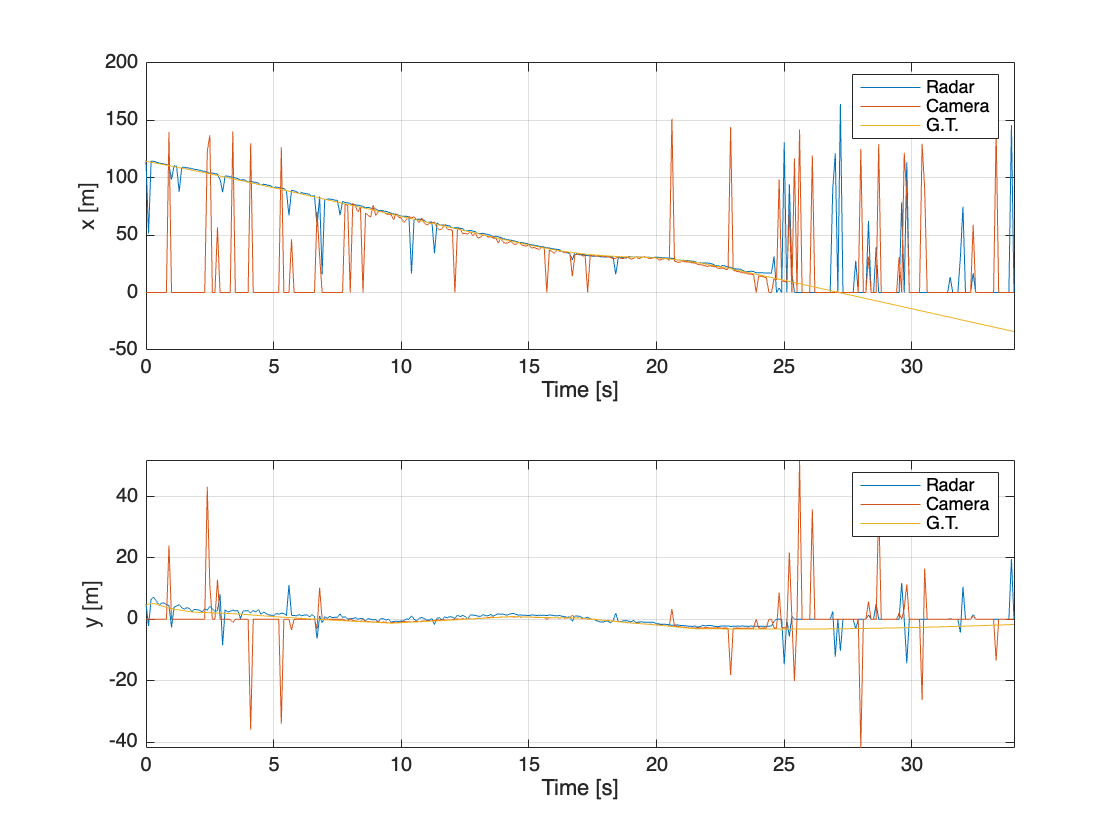

figure;

ax = [];

ax(1) = subplot(2,1,1); box on; hold on; grid on;
plot(time_vec,radar_meas(:,1));
plot(time_vec, camera_meas(:,1));
plot(time_vec,GT(:,1));
ylabel("x [m]");
xlabel("Time [s]");
legend("Radar", "Camera","G.T.");

ax(2) = subplot(2,1,2); box on; hold on; grid on;
plot(time_vec,radar_meas(:,2));
plot(time_vec, camera_meas(:,2));
plot(time_vec,GT(:,2));
ylabel("y [m]");
xlabel("Time [s]");
legend("Radar", "Camera","G.T.");

linkaxes(ax, 'x');
axis tight;

### Relative Speed

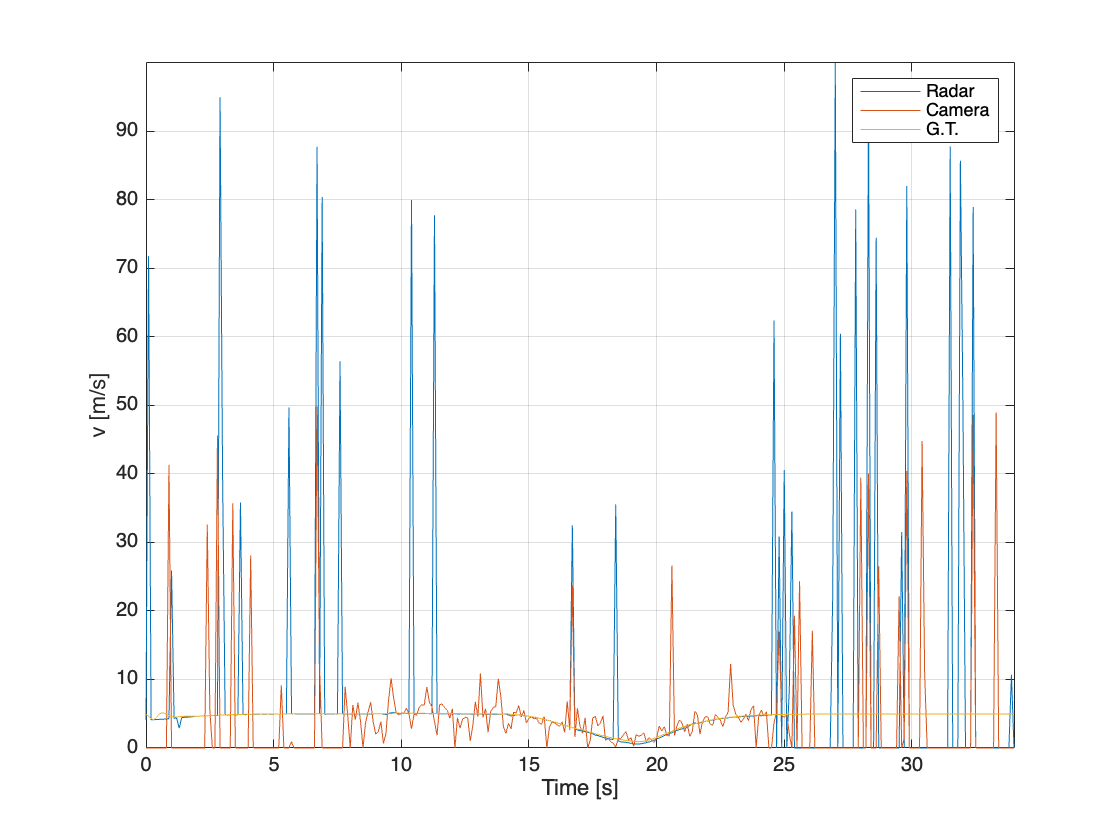

figure;

ax = [];

ax(1) = subplot(1,1,1); box on; hold on; grid on;
plot(time_vec,radar_speed);
plot(time_vec, camera_speed);
plot(time_vec,GT_speed);
ylabel("v [m/s]");
xlabel("Time [s]");
legend("Radar", "Camera","G.T.");

linkaxes(ax, 'x');
axis tight;

#### 
$$v_x$$


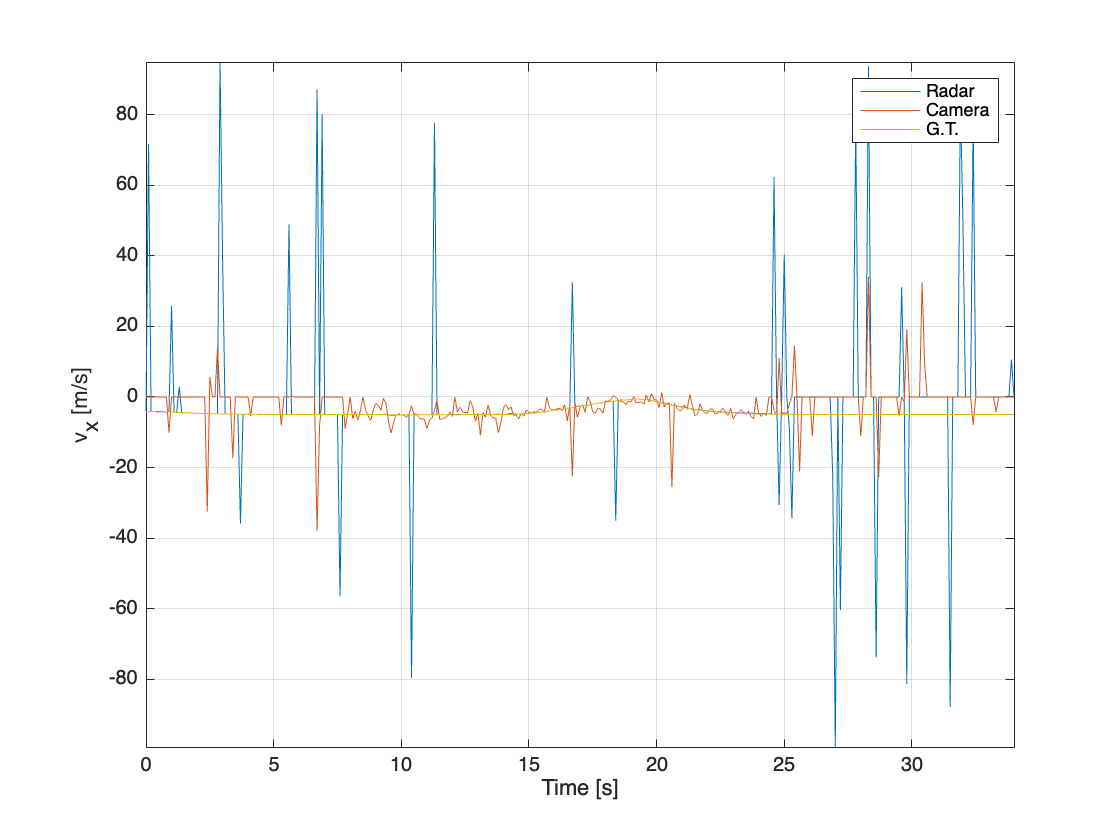

figure;

ax = [];

ax(1) = subplot(1,1,1); box on; hold on; grid on;
plot(time_vec,radar_meas(:,4));
plot(time_vec, camera_meas(:,4));
plot(time_vec,GT(:,4));
ylabel("v_x [m/s]");
xlabel("Time [s]");
legend("Radar", "Camera","G.T.");

linkaxes(ax, 'x');
axis tight;

#### 
$$v_y$$


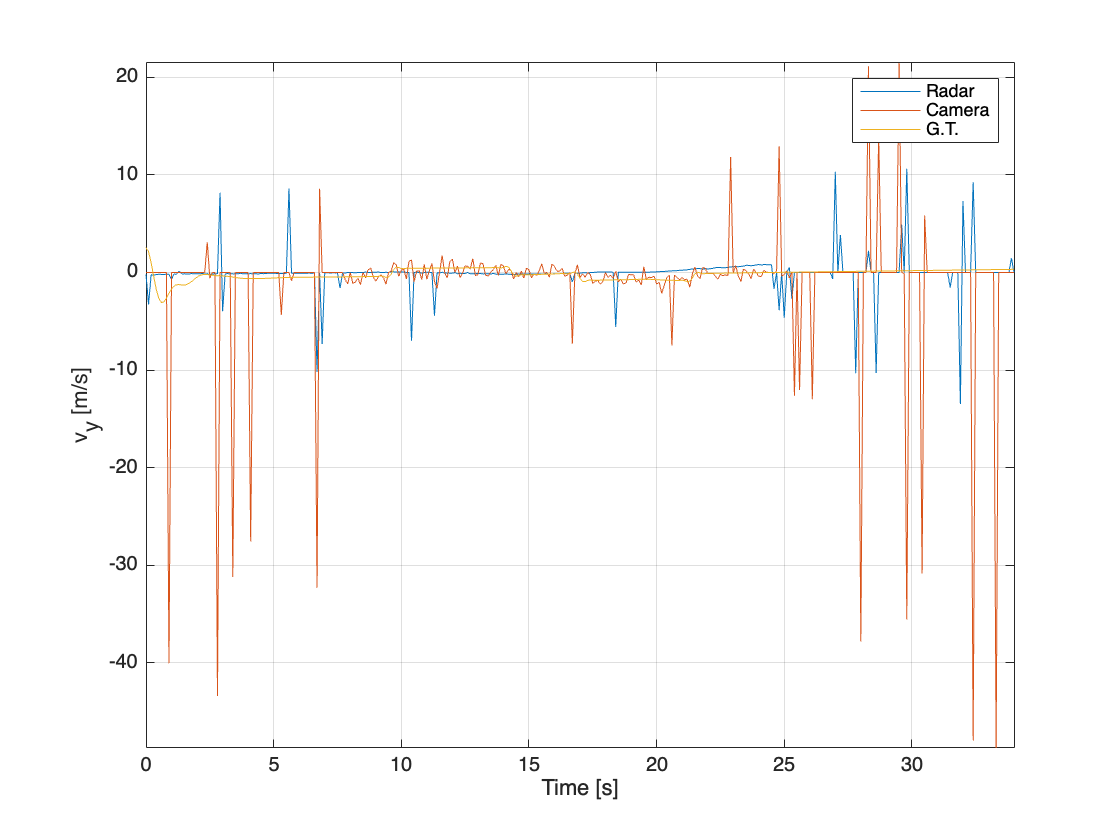

figure;

ax = [];

ax(1) = subplot(1,1,1); box on; hold on; grid on;
plot(time_vec,radar_meas(:,5));
plot(time_vec, camera_meas(:,5));
plot(time_vec,GT(:,5));
ylabel("v_y [m/s]");
xlabel("Time [s]");
legend("Radar", "Camera","G.T.");

linkaxes(ax, 'x');
axis tight;

## Plotting the GT State Vector of the vehicle over time

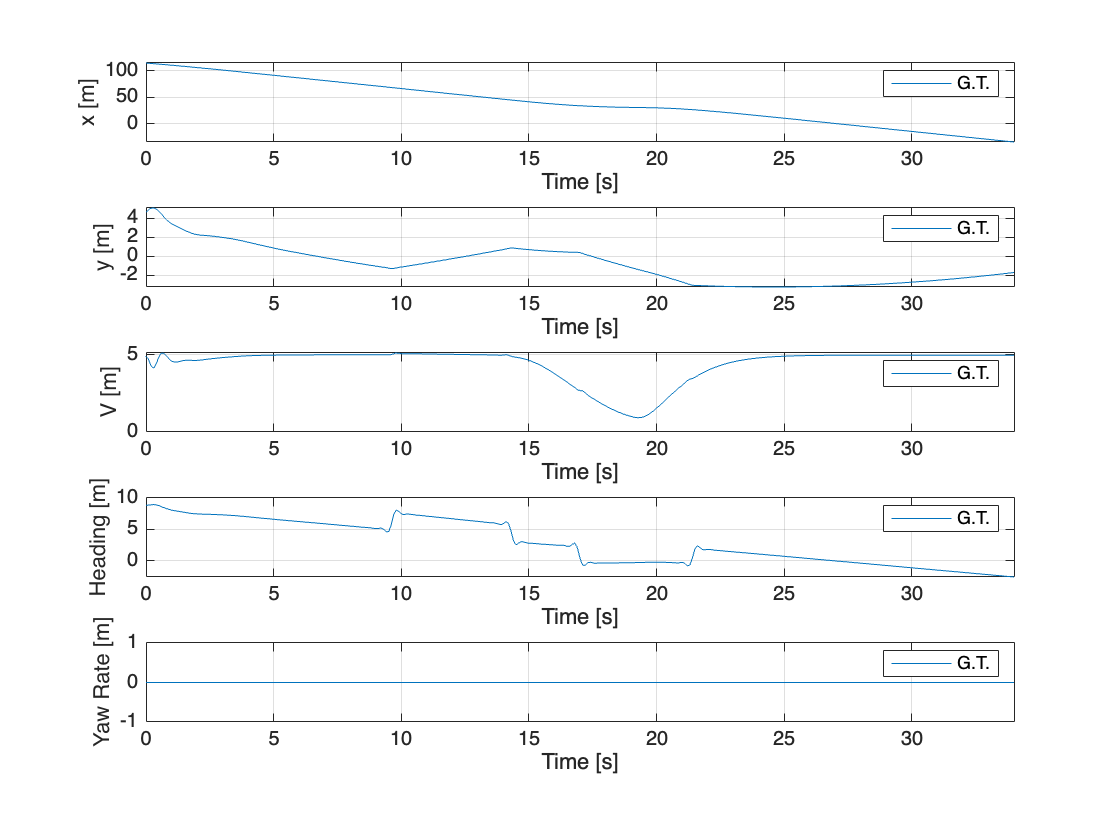

figure;

ax = [];

ax(1) = subplot(5,1,1); box on; hold on; grid on;
plot(time_vec,GT_state(:,1));
ylabel("x [m]");
xlabel("Time [s]");
legend("G.T.");

ax(2) = subplot(5,1,2); box on; hold on; grid on;
plot(time_vec,GT_state(:,2));
ylabel("y [m]");
xlabel("Time [s]");
legend("G.T.");

ax(3) = subplot(5,1,3); box on; hold on; grid on;
plot(time_vec,GT_state(:,3));
ylabel("V [m]");
xlabel("Time [s]");
legend("G.T.");

ax(4) = subplot(5,1,4); box on; hold on; grid on;
plot(time_vec,GT_state(:,4));
ylabel("Heading [m]");
xlabel("Time [s]");
legend("G.T.");

ax(5) = subplot(5,1,5); box on; hold on; grid on;
plot(time_vec,GT_state(:,5));
ylabel("Yaw Rate [m]");
xlabel("Time [s]");
legend("G.T.");

linkaxes(ax, 'x');
axis tight;

### Saving data variables as arrays for convenience

save("time_vector.mat","time_vec");
save("camera_meas_array.mat","camera_meas");
save("camera_speed_array.mat","camera_speed");
save("radar_meas_array.mat","radar_meas");
save("radar_speed_array.mat","radar_speed");
save("GT_array.mat","GT");
save("GT_speed_array.mat","GT_speed");
save("GT_state.mat","GT_state");

## Conclusions

We can see from this analysis the following:

- We can reliably use data only up to t = 25s

- we can see how measurements are noisy

- we can see how the camera suffer from more noisy measurements with respect to the radar.